# **FEECONS Term Project**

**DAYRIT, Bettina Gaille H.**

**GUEVARRA, Gia Kyla S.**

**RODRIGUEZ, Mariah Venice A.**

**SABINO, Cleajane Y.**

**SULIT, Keane Dwight A.**

## BLOCK DIAGRAM REFERNCES

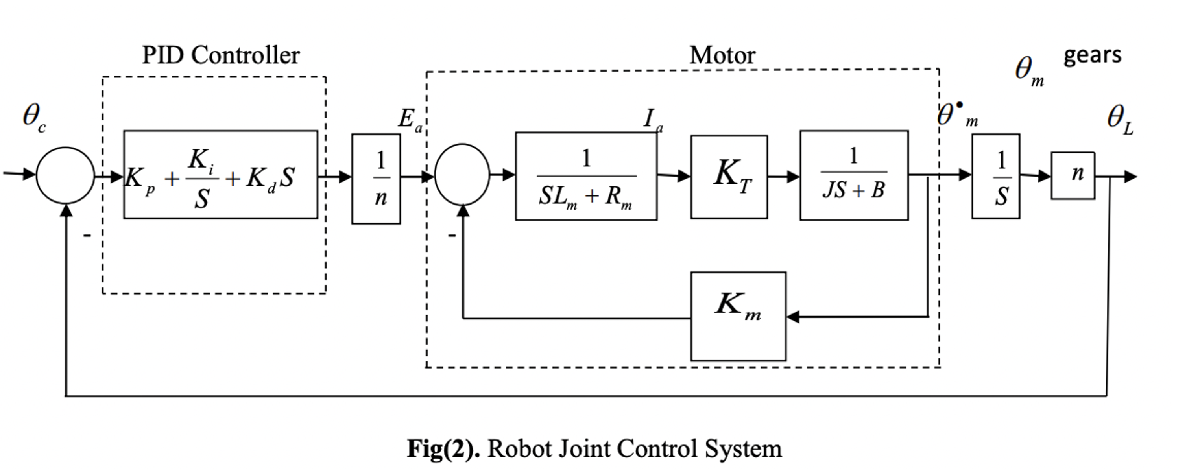

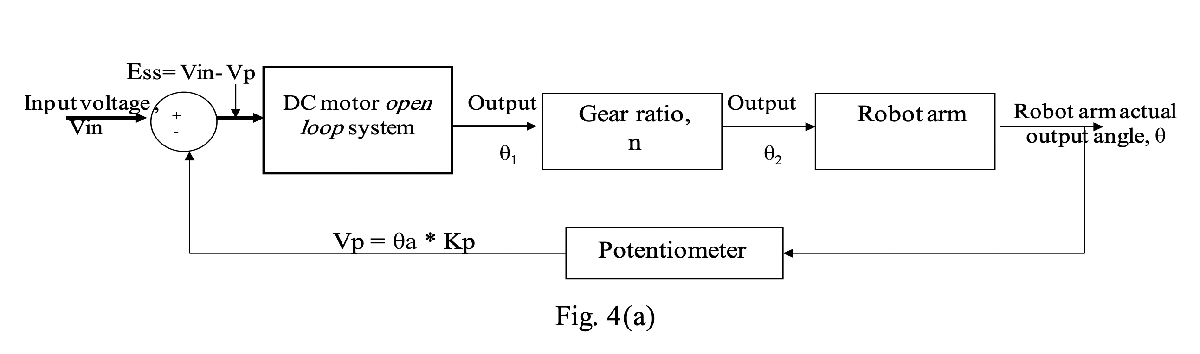

## POSITION CONTROL (ANGULAR POSITION OUTPUT)

### TRANSFER FUNCTION

The transfer function is given by the following (motor and arm)

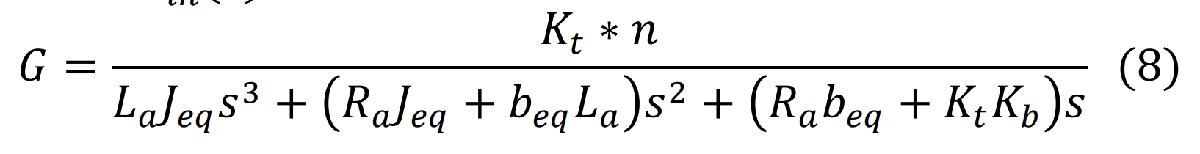

clc, clear all, close all

% Declaring nominal values of the system
J = 0.05; 
b = 0.09;
Kb = 0.020;
Kt = 0.022;
Ra = 2; % in ohms
La = 0.03; % in Henry
V = 12; % in volts
M= 10; 
b_arm= 0.03;
L = 0.5; % in m
n= 1;

% calculating Jload given by the formula, (ml^2)/12
Jload= (M*L^2)/12;

% calculating equivalent values
beq= b_arm + b*n;
Jeq= J + Jload*n;

V_max = input(' Enter maximum allowed voltage , V max : ');
Angle_max = input( 'Enter maximum allowed angle for robot arm : ');

% determining the transfer function [OPEN LOOP] 
num = [Kt*n];
den=[(La*Jeq) (Ra*Jeq+beq*La) (Ra*beq+Kt*Kb) 0];
disp('Robot arm open loop transfer function, Angle/Volt: ')

Robot arm open loop transfer function, Angle/Volt: 


Gs_OLTF =tf(num,den)

Gs_OLTF =
 
                 0.022
  -----------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s
 
Continuous-time transfer function.



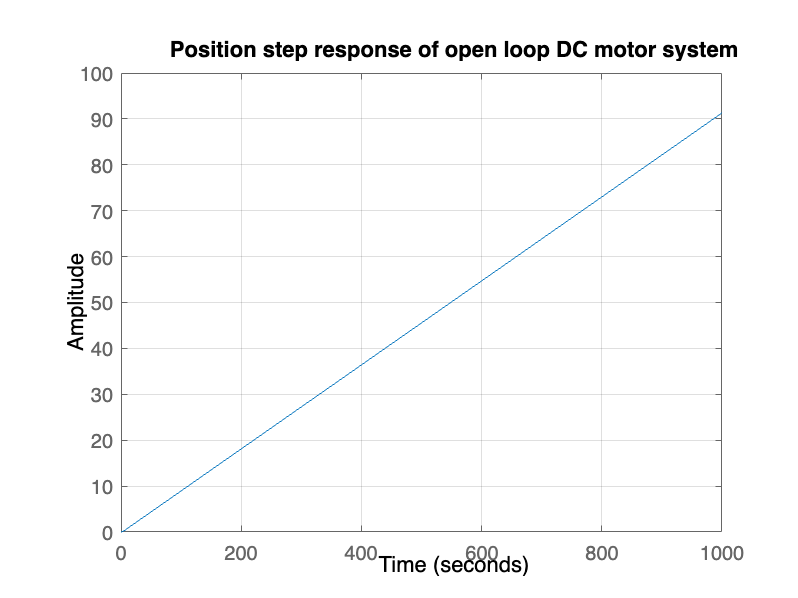

step(Gs_OLTF); title('Position step response of open loop DC motor system'); grid on


% Sensor modelling, Km/Potentiometer
Km =V_max/Angle_max; % potentiometer
Gs_CLTF= feedback(Gs_OLTF,(Km/n))

Gs_CLTF =
 
                     0.022
  --------------------------------------------
  0.00775 s^3 + 0.5203 s^2 + 0.2404 s + 0.0022
 
Continuous-time transfer function.



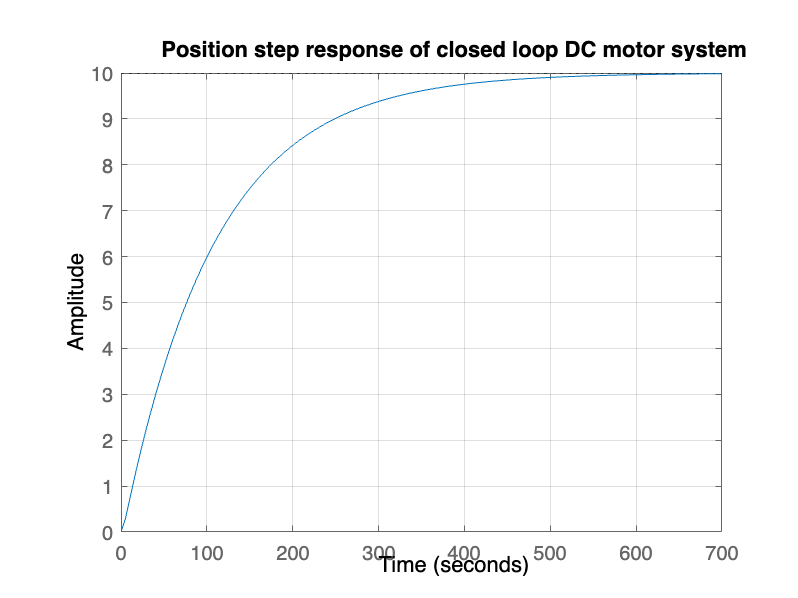

step(Gs_CLTF); title('Position step response of closed loop DC motor system'); grid on


% Getting Initial Time Responses
info_mtr= stepinfo(Gs_CLTF)

info_mtr = struct with fields:
         RiseTime: 235.3006
    TransientTime: 421.1685
     SettlingTime: 421.1685
      SettlingMin: 9.0249
      SettlingMax: 9.9933
        Overshoot: 0
       Undershoot: 0
             Peak: 9.9933
         PeakTime: 784.0838


% getting steady-state error for a step input,
Kp= dcgain(Gs_CLTF);
ess= 1/(1+Kp)

ess = 0.0909

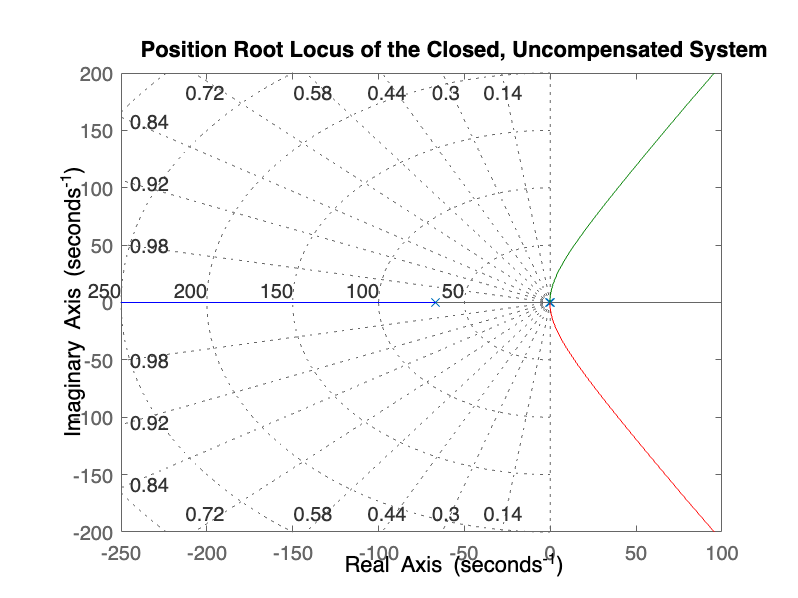


% root locus visualizations
rlocus(Gs_CLTF); grid on; title ('Position Root Locus of the Closed, Uncompensated System')


dena= [0.00775 0.5203 0.2404 0.0022]; % getting the precise value of the poles
poles= roots(dena)

poles =   -66.6703
   -0.4559
   -0.0093


From the given step response info: 

- Settling Time= 421.1685 ... does not satisfy the condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 1%)

- Steady-state error= 0.0909 ... satisfied condition (<=1%)

== **VISUALIZATION**

Control System Designer

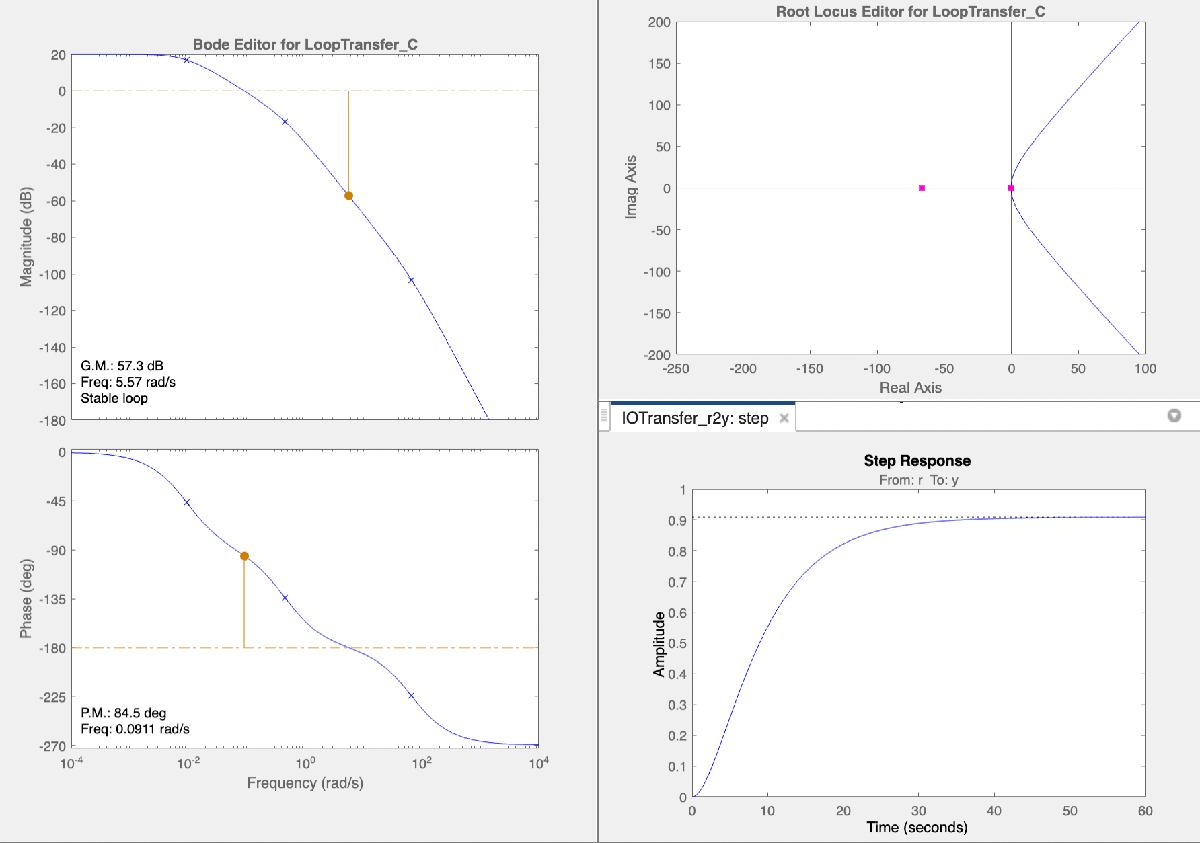

### DETERMINING THE DESIRED POLES

== **DESIGN CRITERIA:**

- Settling Time (Ts) <= 1 second

- % Overshoot <= 1%

- Steady State Error = 1

% ... from the given design criteria:
Ts=1;
PO=0.01;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.8261

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 4.8421

Incorporating the parameters, the given transfer function is now:

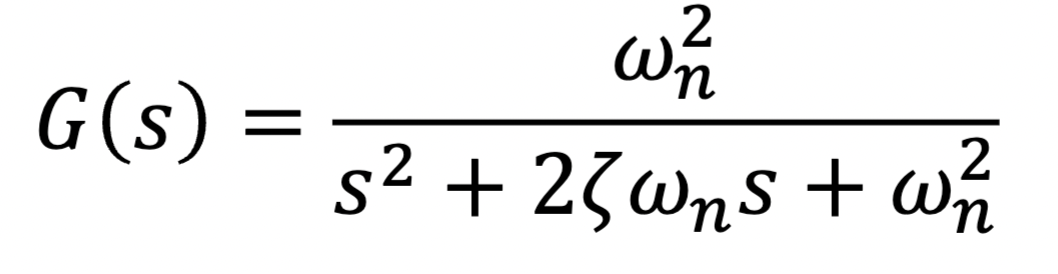

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 2.7288i
  -4.0000 - 2.7288i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 2\ldotp 7288j$ are the desired poles. 

### DESIGNING THE COMPENSATORS  

#### Designing a LEAD Compensator 

% From the poles in the system and shown in the root locus, place a zero
% close to the right most pole, P3= =-0.0093

zlead= 0.009125% approximate (trial and error) value

zlead = 0.0091

Calculations (formula) for Plead:


$$\Sigma \theta_z -\Sigma \theta_p =-180$$


θ4 - (θ1+θ2+θ3+θ5)= -180

Calculations (formula) for the overall gain, 


$$K_{\textrm{overall}} =\frac{\Pi \;\textrm{pole}\;\textrm{lengths}\;}{\Pi \;\textrm{zero}\;\textrm{lengths}\;}=\;\frac{\textrm{L1}\;\textrm{L2}\;\textrm{L3}\;\textrm{L5}}{\textrm{L4}}$$
 

% calculating for the angles
theta1= 180- rad2deg(atan(2.7288/(4-0.4559)))

theta1 = 142.4053

theta2= rad2deg(atan(2.7288/(66.6703-4)))

theta2 = 2.4932

theta3= 180-rad2deg(atan(2.7288/(4-0.0093)))

theta3 = 145.6361

theta4= 180- rad2deg(atan(2.7288/(4-0.009125)))

theta4 = 145.6372

syms x plead
theta5= rad2deg(atan(2.7288/(plead-4)))

$$theta5 = \frac{180\,\mathrm{atan}\left(\frac{3411}{1250\,\left(\mathrm{plead}-4\right)}\right)}{\pi }$$


% solve for plead
te= theta4-(theta1+theta2+theta3);
eq= 180+te

eq = 35.1026

eqn = rad2deg(atan(2.7288/(x-4))) == 35.1026;
solve(eqn, x);
eqn = rad2deg(tan(atan(2.7288/(x-4)))) == rad2deg(tan(35.1026));
solve(eqn, x);
double(ans)

ans = 8.5003


plead= 66+8.5003;

% Solving for K;
L1= sqrt((2.7288)^2+(4-0.4559)^2);
L2= sqrt((2.7288)^2+(66.6703-4)^2);
L3= sqrt((2.7288)^2+(4-0.0093)^2);
L4= sqrt((2.7288)^2+(4-0.009125)^2);
L5= sqrt((2.7288)^2+(plead-4)^2);
K= (L1*L2*L3*L5)/L4;

% the given transfer function for a lead compensator is:
num2= K*[1 zlead]; 
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  1.98e04 s + 180.6
  -----------------
      s + 74.5
 
Continuous-time transfer function.




positiontfLDC= LDCtf*Gs_CLTF; % transfer function of the system compensated using a lead controller
positiontfLDC_feedback= feedback(positiontfLDC, 1)

positiontfLDC_feedback =
 
                   435.5 s + 3.974
  --------------------------------------------------
  0.00775 s^4 + 1.098 s^3 + 39 s^2 + 453.4 s + 4.138
 
Continuous-time transfer function.



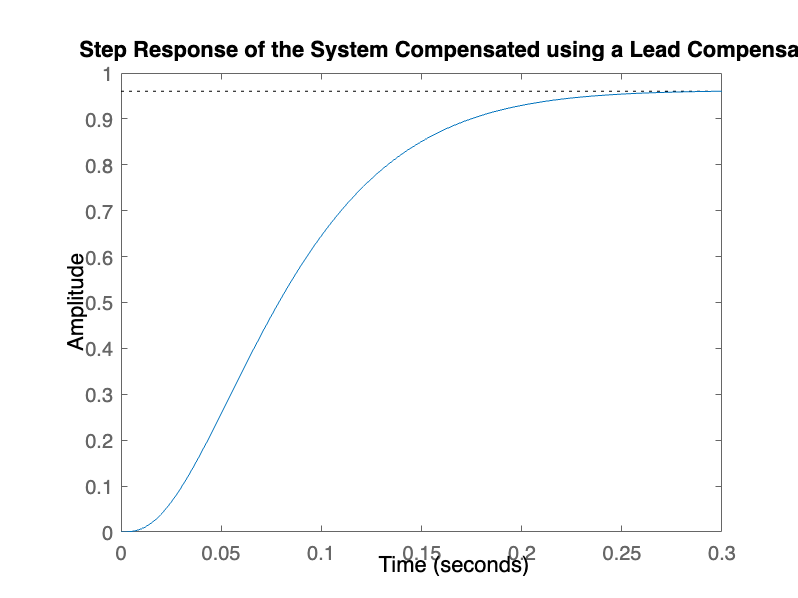


figure (1);
step(positiontfLDC_feedback); title('Step Response of the System Compensated using a Lead Compensator');

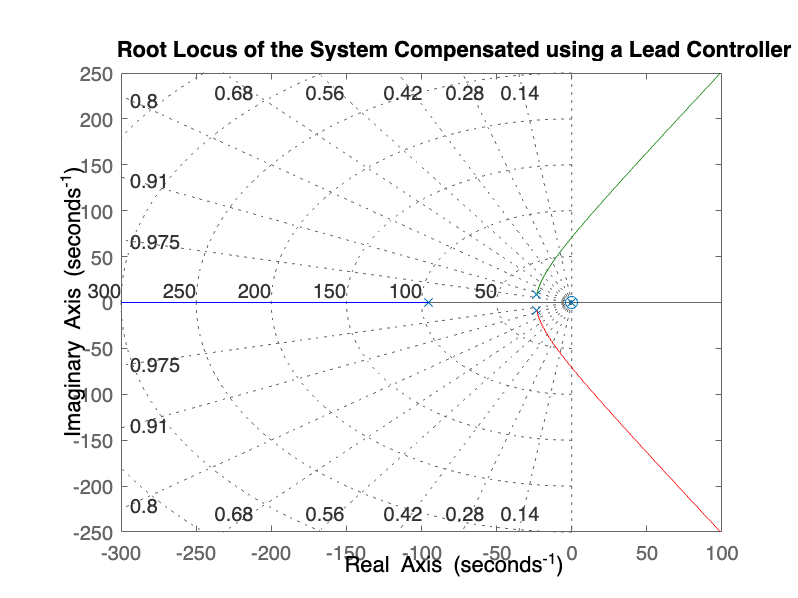

rlocus(positiontfLDC_feedback); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(positiontfLDC_feedback)

info_motorLDC = struct with fields:
         RiseTime: 0.1258
    TransientTime: 0.2165
     SettlingTime: 0.2165
      SettlingMin: 0.8671
      SettlingMax: 0.9614
        Overshoot: 0.1080
       Undershoot: 0
             Peak: 0.9614
         PeakTime: 0.3555


% getting steady-state error for a step input,
Kp1= dcgain(positiontfLDC_feedback);
essLDC= 1/(1+Kp1)

essLDC = 0.5101

**== COMMENTS**

From the given step response info: 

- Settling Time= 0.2165 ... satisfied condition (<= 1 second)

- Overshoot= 0.1080% ... satisfied condition (<= 1%)

- Steady-state error= 0.5101 ...satisfied condition  (<=1)

#### Designing a LAG Compensator 

% From the computed transfer function, Gs_CLTF, the system is a Type 0 system.

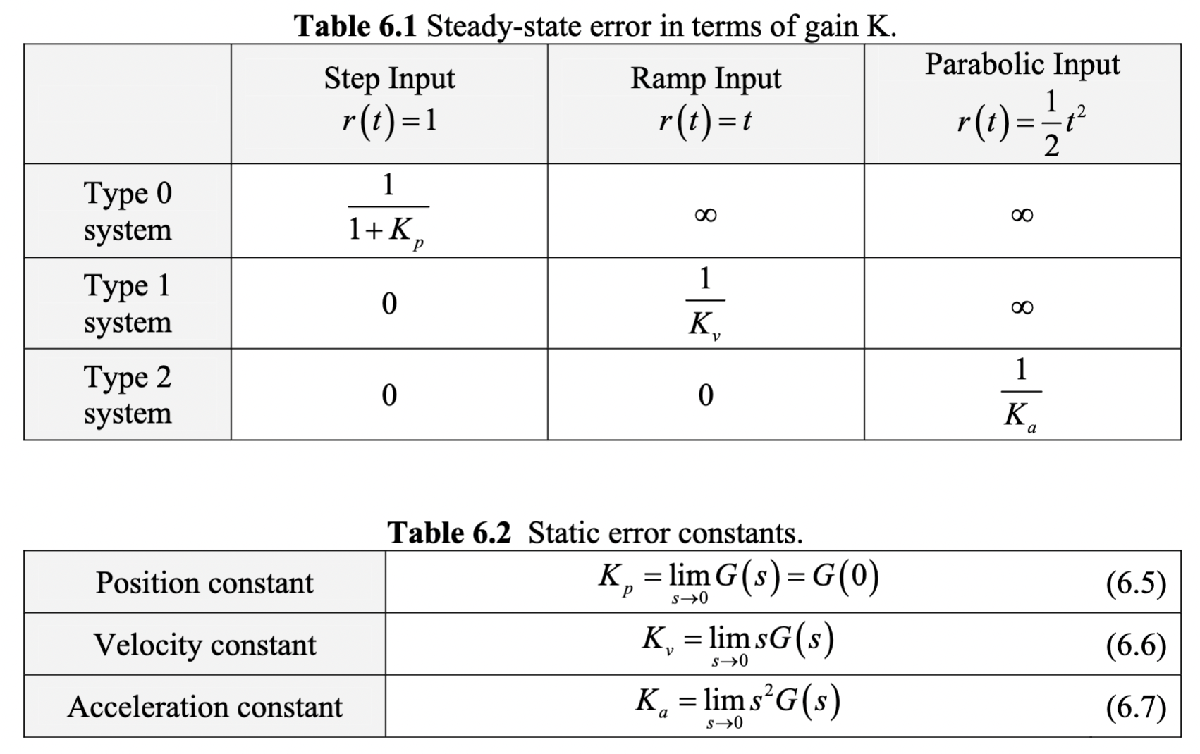

Calculations (formula) for the overall gain, 


$$K_{\mathrm{overall}} =\frac{1\;}{|G\left(s\right)H\left(s\right)|\;}$$


% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kp= 0.022/0.0022; % s appproaches 0, therefore s=0
elead= 1/(1+Kp);
% Assume a value of Plag close to the origin,
plag= 5.5;
zlag= (elead*plag)/SSE;

% solving for K:
K1= 1/((zlag/plag)*(0.022/.0022));

% the given transfer function for a lag compensator is:
num3= K1*[1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  1.1 s + 0.55
  ------------
    s + 5.5
 
Continuous-time transfer function.




positiontfLGC= LGCtf*Gs_CLTF; % transfer function of the system compensated using a lag controller
positiontfLGC_feedback= feedback(positiontfLGC, 1)

positiontfLGC_feedback =
 
                     0.0242 s + 0.0121
  -------------------------------------------------------
  0.00775 s^4 + 0.5629 s^3 + 3.102 s^2 + 1.349 s + 0.0242
 
Continuous-time transfer function.



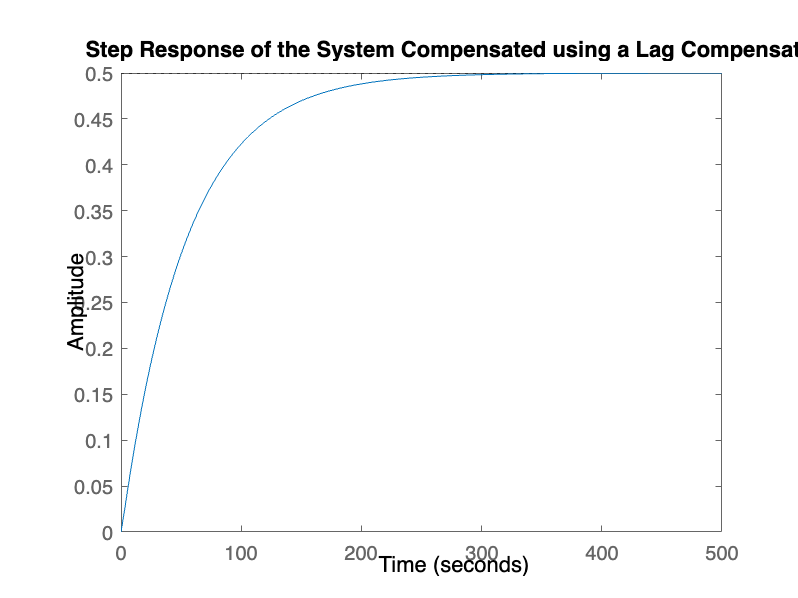


figure (2);
step(positiontfLGC_feedback); title('Step Response of the System Compensated using a Lag Compensator');

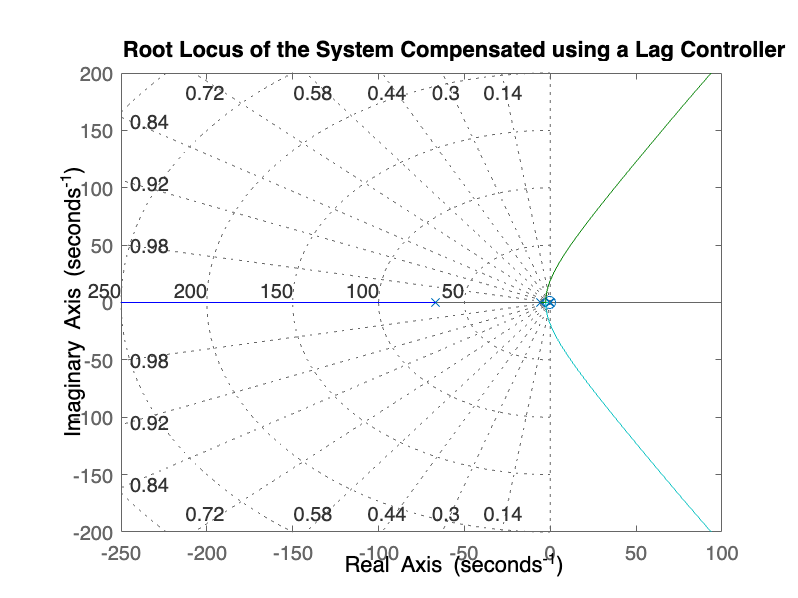

rlocus(positiontfLGC_feedback); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(positiontfLGC_feedback)

info_motorLGC = struct with fields:
         RiseTime: 117.2160
    TransientTime: 209.0823
     SettlingTime: 209.0823
      SettlingMin: 0.4519
      SettlingMax: 0.5000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.5000
         PeakTime: 562.5317


% getting steady-state error for a step input,
Kp2= dcgain(positiontfLGC_feedback);
essLGC= 1/(1+Kp2)

essLGC = 0.6667

From the given step response info: 

- Settling Time= 90.6262 ... does not satisfy the condition (<= 1 second)

- Overshoot= 49.7916 ... does not satisfy condition (<= 1%)

- Steady-state error= 0.5023 ...satisfied condition  (<=1)

#### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numfa= [1 zlead];
numfb= [1 zlag];
denfa= [1 plead];
denfb= [1 plag];
numf= K*K1*conv(numfa,numfb);
denf= conv(denfa, denfb);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  2.178e04 s^2 + 1.109e04 s + 99.35
  ---------------------------------
         s^2 + 80 s + 409.8
 
Continuous-time transfer function.




positiontfLDGC= Gs_CLTF*LDGCtf; % transfer function of the system compensated using a lead-lag controller
positiontfLDGC_feedback= feedback(positiontfLDGC, 1)

positiontfLDGC_feedback =
 
                    479.1 s^2 + 243.9 s + 2.186
  ----------------------------------------------------------------
  0.00775 s^5 + 1.14 s^4 + 45.04 s^3 + 711.5 s^2 + 342.6 s + 3.087
 
Continuous-time transfer function.



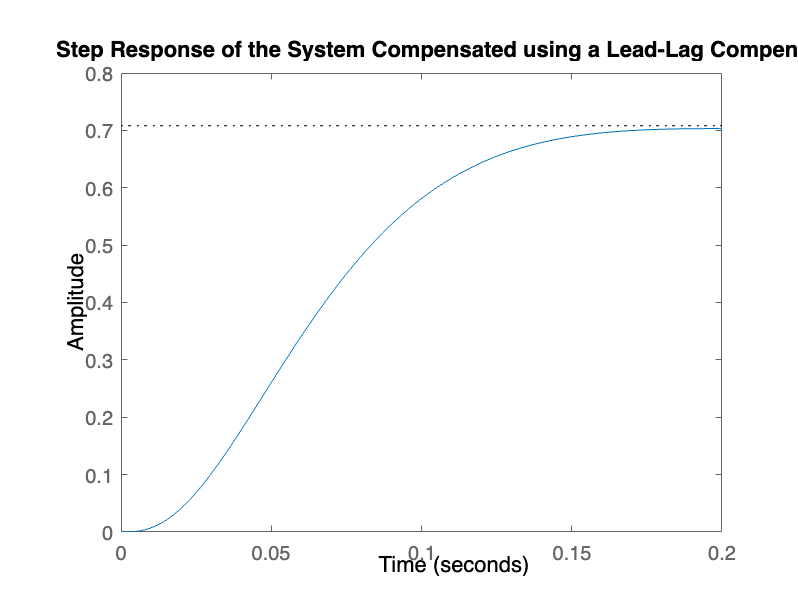


figure (3);
step(positiontfLDGC_feedback); title('Step Response of the System Compensated using a Lead-Lag Compensator');

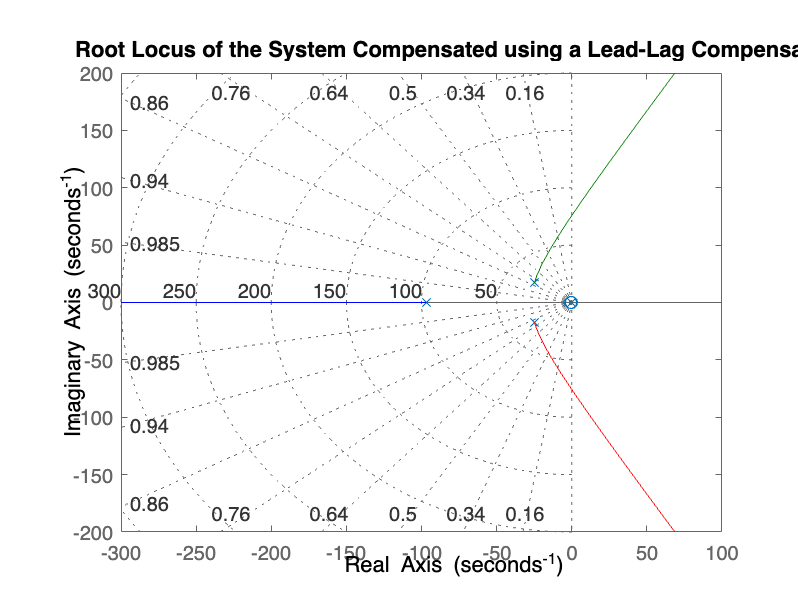

rlocus(positiontfLDGC_feedback); grid on; title('Root Locus of the System Compensated using a Lead-Lag Compensator');

info_motorLDGC= stepinfo(positiontfLDGC_feedback)

info_motorLDGC = struct with fields:
         RiseTime: 0.0919
    TransientTime: 0.1568
     SettlingTime: 0.1568
      SettlingMin: 0.6402
      SettlingMax: 0.7031
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7031
         PeakTime: 0.1962


% getting steady-state error for a step input,
Kp3= dcgain(positiontfLDGC_feedback);
essLDGC= 1/(1+Kp3)

essLDGC = 0.5855

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.2918 ... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 1%)

- Steady-state error= 0.5009 ... satisfied condition (<=1%)